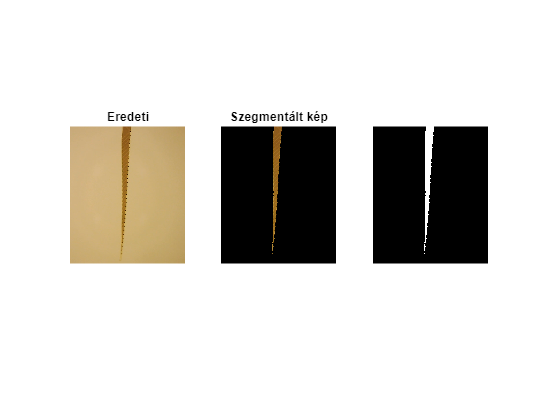

clear all
close all

RGB=imread("");

[BW, maskedImage] = segmentImage(RGB);

figure();
subplot(131);
imshow(RGB);
title("Eredeti");
subplot(132);
imshow(maskedImage);
title("Szegmentált kép");
subplot(133);
imshow(BW);

function [BW,maskedImage] = segmentImage(RGB)

X = rgb2lab(RGB);

s = rng;
rng("default");
L = imsegkmeans(single(X),2,"NumAttempts",2);
rng(s);
BW = L == 2;

maskedImage = RGB;
maskedImage(repmat(~BW,[1 1 3])) = 0;
end